Predict the proportions for the color

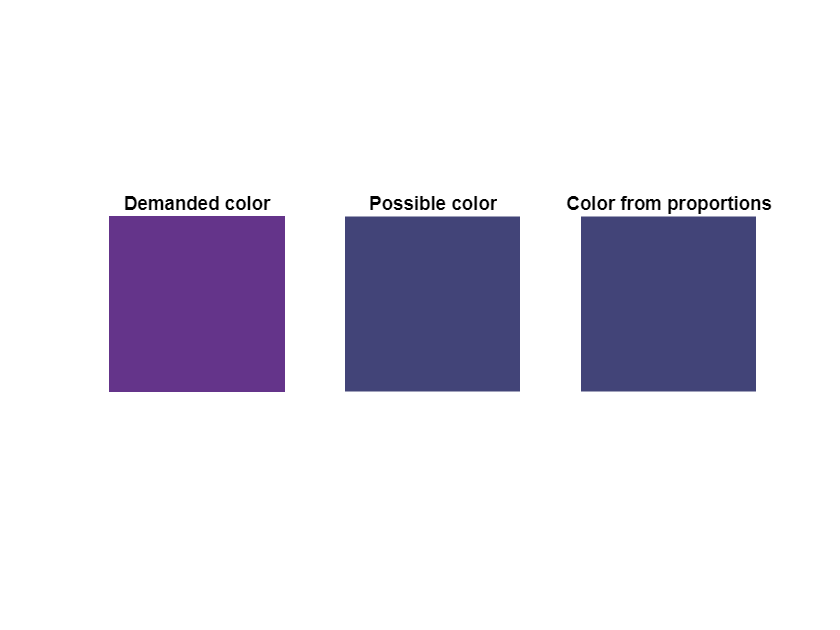

tablename = 'ModelTable600.xls';
Ycell = cell(1,4); % 0 1 2 3 = MY1 MY2 CY CM
Wcell = cell(1,4);

for i = 1:4
    M1 = readmatrix(tablename,'Sheet',i);
    Ycell{i} = M1(:,1:3);
    Wcell{i} = M1(:,4:6);
end

%create HSV color
H = 0.76;
S = 0.62;
V = 0.54;
[props, cls, hsvnew] = PredictProportions([H S V],Ycell,Wcell);
col8 = prop2pp(props,cls);

[hsv2,props2] = col82hsv(col8,Wcell,Ycell);
strcol = '';
for i = 1:3
    strcol = [strcol,' ',num2str(props2(i))];
end

rgbcol = hsv2rgb([H S V]);
rgbnew = hsv2rgb(hsvnew);
rgb2 = hsv2rgb(hsv2);
N = 100;

img = double(zeros(N,N,3));
imgnew = img;
img2 = img;
for i = 1:3
    img(:,:,i) = rgbcol(i)*ones(N);
    imgnew(:,:,i) = rgbnew(i)*ones(N);
    img2(:,:,i)= rgb2(i)*ones(N);
end
figure;
subplot(1,3,1);
imshow(img);
title('Demanded color');
subplot(1,3,2);
imshow(imgnew);
title('Possible color');
subplot(1,3,3);
imshow(img2);
title('Color from proportions');

disp(['HSV___ = [',num2str(H),' ',num2str(S),' ',num2str(V),']']);

HSV___ = [0.76 0.62 0.54]


disp(['HSVnew = [',num2str(hsvnew(1)),' ',num2str(hsvnew(2)),' ',num2str(hsvnew(3)),']']);

HSVnew = [0.66169 0.44718 0.47055]


disp(['Props = [',strcol,']']);

Props = [ 0.45894 0.43442 0.64155]


disp(['HSV2 = [',num2str(hsv2(1)),' ',num2str(hsv2(2)),' ',num2str(hsv2(3)),']']);

HSV2 = [0.6617 0.44716 0.47053]



switch cls
    case {1,2}
        v1 = 'M/(M + Y)';
    case 3
        v1 = 'Y/(Y + C)';
    case 4
        v1 = 'C/(C + M)';
end
T = table(props(1),props(2),props(3), 'VariableNames',{v1, 'b/(b + w)', 'hue/all'});
disp(T);

    C/(C + M)    b/(b + w)    hue/all
    _________    _________    _______

     0.45896      0.43436     0.64154



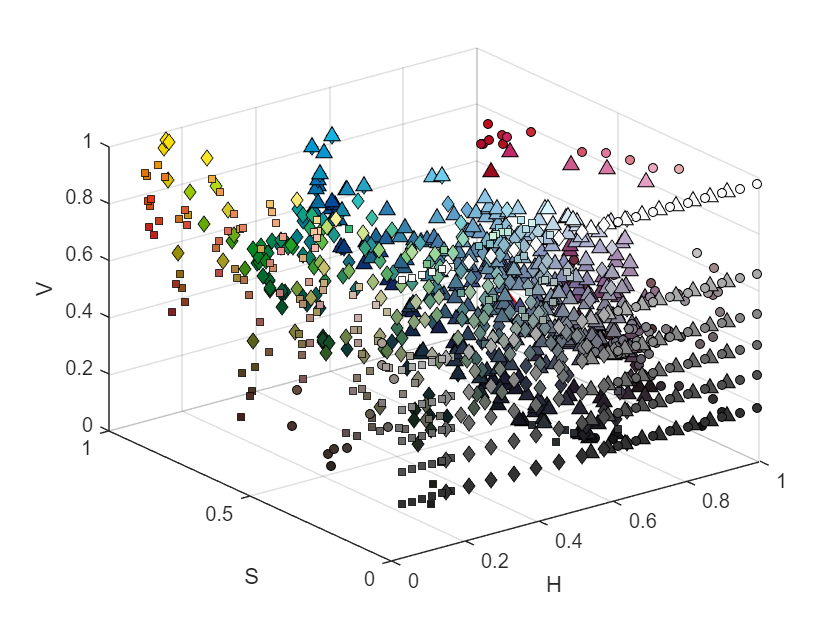


show3d = true;
if show3d
    figure;
    markers = {'o','s','d','^'};
    markersizes = {20,20,30,50};
    for i = 1:4
        Y = Ycell{i}; %HSV
        scatter3(Y(:,1),Y(:,2),Y(:,3),markersizes{i},hsv2rgb(Y),markers{i},'filled','MarkerEdgeColor','k'); hold on
    end
    xlabel('H');
    ylabel('S');
    zlabel('V');

    scatter3(H,S,V,70,rgbcol,'s','filled','MarkerEdgeColor','g','LineWidth',1);
    scatter3(hsvnew(1),hsvnew(2),hsvnew(3),50,rgbnew,'o','filled','MarkerEdgeColor','g','LineWidth',1);
    scatter3(hsv2(1),hsv2(2),hsv2(3),70,rgb2,'d','filled','MarkerEdgeColor','r','LineWidth',1);
end